# Lab S8

Spline cúbico natural

format rational

x = [1 5 10 12]';
y = [5 10 15 25]';

% Tabla para hallar hi y diferencias divididas
tabla = difdiv_spline(x,y)

tabla =    1.000000000000000   5.000000000000000   4.000000000000000   1.250000000000000                   0
   5.000000000000000  10.000000000000000   5.000000000000000   1.000000000000000                   0
  10.000000000000000  15.000000000000000   2.000000000000000   5.000000000000000                   0
  12.000000000000000  25.000000000000000                   0                   0                   0



% Tabla para hallar la matrix M
M = matrix_spline(tabla);
M = [0; M; 0]

M =                    0
  -0.621145374449339
   1.936123348017621
                   0



% Tabla de coeficientes
coef = coef_spline(tabla, M)

coef =   -0.025881057268722                   0   1.664096916299559   5.000000000000000
   0.085242290748899  -0.310572687224670   0.421806167400881  10.000000000000000
  -0.161343612334802   0.968061674008811   3.709251101321586  15.000000000000000



% Funciones
func_spline(x, coef)

ans = 3×1 cell array
    {                                         @(x)x.*1.664096916299559-(x-1.0).^3.*2.588105726872247e-2+3.335903083700441}
    {         @(x)x.*(3.83e+2./9.08e+2)-(x-5.0).^2.*(1.41e+2./4.54e+2)+(x-5.0).^3.*8.524229074889868e-2+7.890969162995595}
    {@(x)x.*(8.42e+2./2.27e+2)+(x-1.0e+1).^2.*(8.79e+2./9.08e+2)-(x-1.0e+1).^3.*1.613436123348018e-1-2.209251101321586e+1}


x = [0,1,2,3,4]

x =        0              1              2              3              4       


y = sin(pi*x/2)

y =        0              1              *             -1              *       


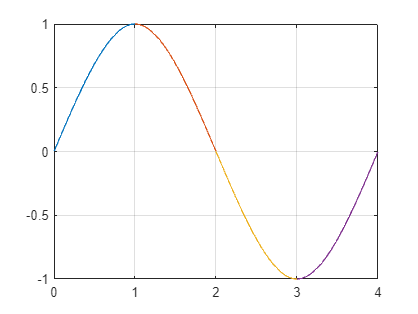

spline =       -1/2            0              3/2            0       
       1/2           -3/2            *              1       
       1/2            *             -3/2            *       
      -1/2            3/2            *             -1       



spline = splinenatural(x, y)


sumacoef = sum(spline(1,:))

sumacoef =        1       



syms z
func = matlabFunction(spline(2, 1)*((z - x(2))^3) + spline(2,2)*((z - x(2))^2) + spline(2,3)*(z - x(2)) + spline(2,4));
fvalue = func(1.5)

fvalue =      -11/16    


dfunc = diff(func, z);
dfunc = matlabFunction(dfunc);
dfvalue = dfunc(1.5)

dfvalue =       -9/8     


ddfunc = diff(dfunc, z);
ddfunc = matlabFunction(ddfunc);
df2value = ddfunc(1)

df2value =        0       


a0=2;
b0=1;
c0=2;
d0=1;
x0=1;
p=convierte(a0,b0,c0,d0,x0)

p =        2             -5              6             -2       


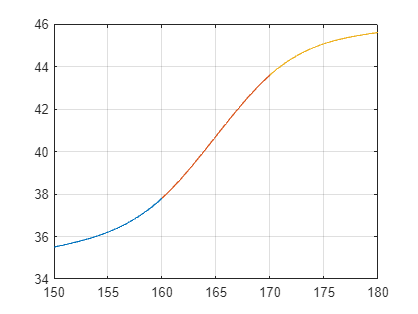

spline =     0.0012         0    0.1113   35.5000
   -0.0024    0.0356    0.4673   37.8000
    0.0012   -0.0374    0.4493   43.6000


Index exceeds the number of array elements. Index must not exceed 1.

Error in indexing (line 936)
            R_tilde = builtin('subsref',L_tilde,Idx);

format shortSx, y)

    n = length(x);
    M = zeros(n);
    M = [x M];
    M(:,2) = y;

    for k = 1:n-1
        hi = x(k+1) - x(k);
        M(k, 3) = hi;
        delta_y = y(k+1) - y(k);
        delta_x = x(k+1) - x(k);
        M(k,4) = delta_y/delta_x;
    end
end

function M = matrix_spline(tabla)
    [m, ~] = size(tabla);
    A = zeros(m-2);

    for k = 1:m-3
        A(k, k) = 2*(tabla(k+1, 3) + tabla(k, 3));
        A(k,k+1) = tabla(k+1, 3);
        A(k+1,k) = tabla(k+1, 3);
    end

    A(m-2, m-2) = 2*(tabla(m-1, 3) + tabla(m-2, 3));

    b = 6*(diff(tabla(1:m-1,4)));

    M = linsolve(A, b);
end

function sol = coef_spline(tabla, M)
    [m, ~] = size(tabla);
    sol = zeros(m-1, 4);

    for k = 1:m-1
        sol(k, 1) = (M(k+1) - M(k))/(6*tabla(k,3));
        sol(k, 2) = M(k)/2;
        sol(k, 3) = tabla(k,4) - ((M(k+1)+2*M(k))*tabla(k,3)/6);
        sol(k, 4) = tabla(k,2);
    end
end

function func = func_spline(val, coef)
    [m, ~] = size(coef);
    func = cell(m,1);
    syms x

    for k = 1:m
        func{k} = matlabFunction(coef(k,1)*((x - val(k))^3) + coef(k,2)*((x - val(k))^2) + coef(k,3)*(x - val(k)) + coef(k,4));
    end
end


Spline natural completo

function S=splinenatural(X,Y)
    N=length(X)-1;
    H=diff(X);
    E=diff(Y)./H;
    diagprinc=2*(H(1:N-1)+H(2:N));
    diagsupinf=H(2:N-1);
    g0=0; gn=0;
    A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b=6*diff(E');
    g=A\b;
    g = [g0 g' gn];

    for i=1:N
        S(i,1)=(g(i+1)-g(i))/(6*H(i));
        S(i,2)=g(i)/2;
        S(i,3)=E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4)=Y(i);
        xx=linspace(X(i),X(i+1),100);
        yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy)
        hold on
    end
    grid on
    hold off
end


function p=convierte(a0,b0,c0,d0,x0)
%Complete aquí
    syms x
    p = a0*((x - x0)^3) + b0*((x - x0)^2) + c0*(x - x0) + d0;

    p = expand(p);

    p = coeffs(p, x, 'All');

    p = double(p);
end